# Class 20/10

### 5.8 Improfile

Pour connâitre les niveaux de gris sur 1 courbe particulière, on utilise **improfile** + clic souis ou **improfile(i,x,y)** avec x contenant les abs de pts de la ligne et y contenant les ord des pts de la collone

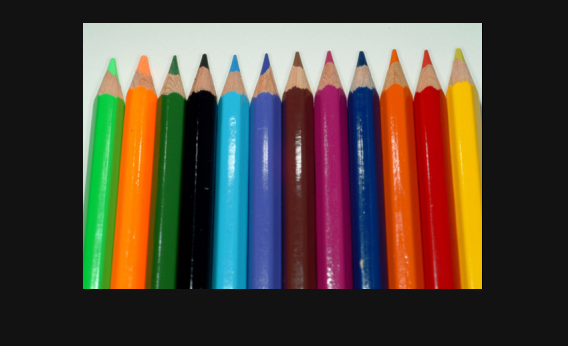

clc; clear; close all;
I = imread("images\crayons_couleurs.png");
figure()
imshow(I);

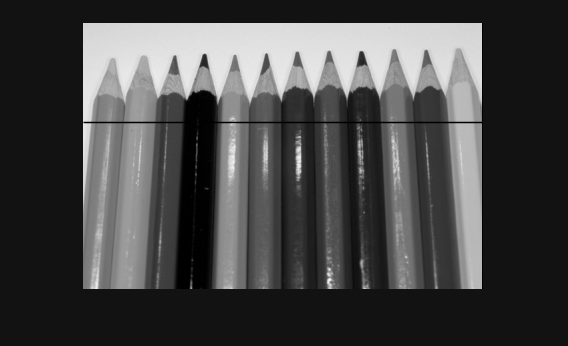

I = rgb2gray(I);
figure();
imshow(I);
hold on;
plot([1 400], [100 100], '-k')

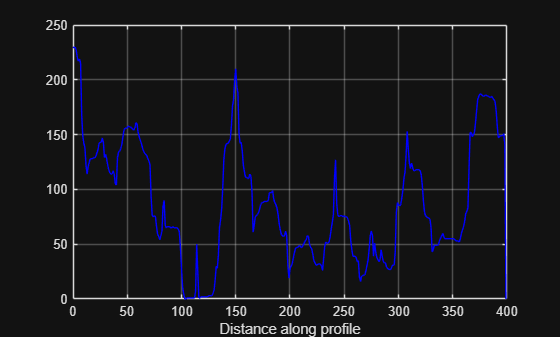

x = [1 400];
y = [100 100];
figure();
improfile(I,x,y)
grid on

### 5.9 Seuillage

Rappel: im2bw permet de transformer une image en niveau de gis en image binaire

On peut ajouter le seuil J = **im2bw**(I, level)

òu level est le seuil discriminent entre noir et blanc (entre 0 et 1)

le seuil peut être détermine par la methode otsu **greythresh**

level = graythresh(I)

level = 0.4706

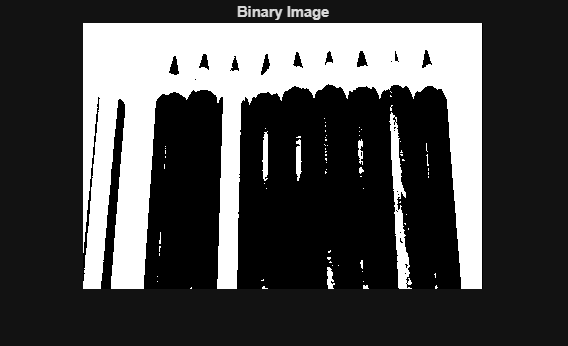

bwImage = imbinarize(I, level);
figure();
imshow(bwImage);
title('Binary Image');

### 5.10 Filtrage

Pour créer un filtre "moyen" on écrit 

**h = fspecial('average');**

**imfilter(I,h);**

Ce filtre lisse l'image et la rend légèrement floue. Idem avec filtre "median" "gaussian"

### 5.11 Bruit

Pour ajouter du bruit à l'image

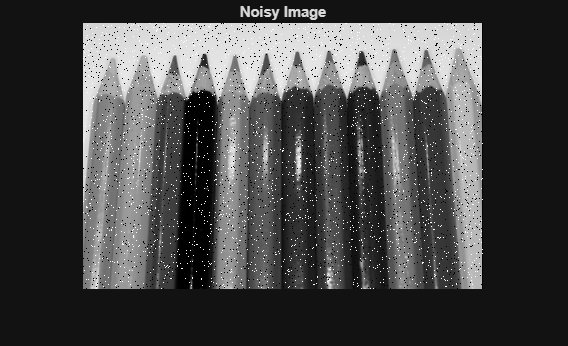

J = imnoise(I, "salt & pepper");
figure();
imshow(J);
title('Noisy Image');

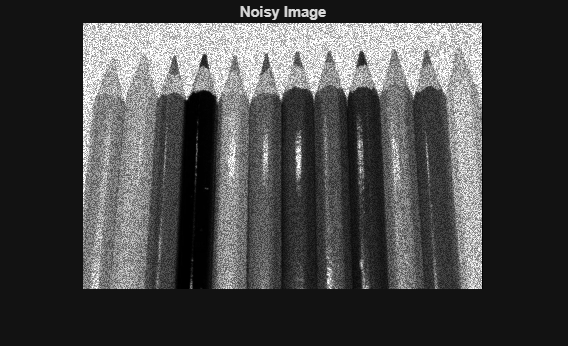

J = imnoise(I, "speckle");
figure();
imshow(J);
title('Noisy Image');

### 5.12 Détection de contours 

Sur l'image binaire ou en niveaux de gris, on peut déetecter les contours avec

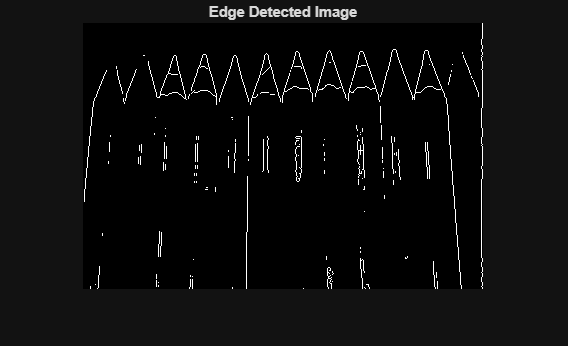

J = edge(I, "prewitt");
figure();
imshow(J);
title('Edge Detected Image');

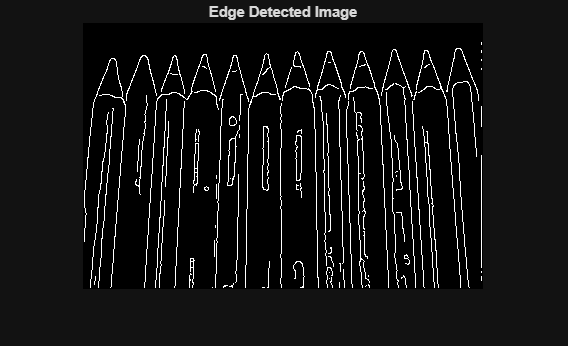

J = edge(I, "canny");
figure();
imshow(J);
title('Edge Detected Image');

### 5.13 Image Binaire

ex: Afficher l'image binaire à partir de l'image en niveaux de gris en utilisant le seuillage automatique (methode otsu). Quel est la valeur de pixel seuil?

level = graythresh(I)

level = 0.4706

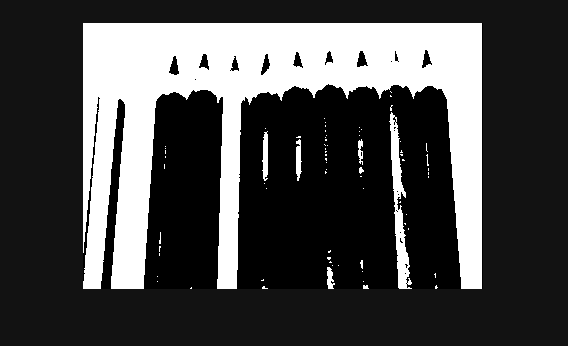

IBW = im2bw(I, level);
figure;
imshow(IBW);

%area 
bwarea(IBW)

ans = 4.9749e+04

%contours
bwboundaries(IBW)

ans = 100×1 cell array
    {2822×2 double}
    {   2×2 double}
    {   2×2 double}
    {  24×2 double}
    {  12×2 double}
    {   5×2 double}
    {   9×2 double}
    {   2×2 double}
    {   2×2 double}
    {   7×2 double}
    {   3×2 double}
    {   4×2 double}
    {   6×2 double}
    { 106×2 double}
    {  13×2 double}
    {   2×2 double}


%properties
regionprops(IBW, "Perimeter")

ans = 73×1 struct array with fields:
    Perimeter


%Extraire de l'image binarisée le rectangle dont les coins offrés ont pour
%coordonnés (200, 20) et (230, 60). Inverser des couleurs. écrire s =
%regionprops(IBW, 'Area', 'centroid' 'BoundingBox', 'EquivDiameter').
%Donner l'aire de la region blanche; Placer une croux rouge au centre;
%Tracer le rectangle englobant la region blanche. Tracer le cercle
%equivalent
x = [200 20];
y = [230, 60];

%           xmin ymin width height
J = imcrop(bwImage, [200 20 30 40]);
J = imcomplement(J);
figure();
imshow(J);
s = regionprops(J, 'Area', 'centroid', 'BoundingBox', 'EquivDiameter')

s = struct with fields:
             Area: 84
         Centroid: [16.2857 19.3095]
      BoundingBox: [11.5000 10.5000 10 16]
    EquivDiameter: 10.3418


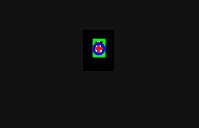

hold on 
centroid = s.Centroid;
plot(centroid(1), centroid(2), 'r+', 'MarkerSize', 10, 'LineWidth', 2);
boundingBox = s.BoundingBox;
rectangle('Position', boundingBox, 'EdgeColor', 'g', 'LineWidth', 2);
equivDiameter = s.EquivDiameter;
theta = linspace(0, 2*pi, 100);
xCircle = centroid(1) + (equivDiameter/2) * cos(theta);
yCircle = centroid(2) + (equivDiameter/2) * sin(theta);
plot(xCircle, yCircle, 'b-', 'LineWidth', 2);